clear all;

addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

load('./completeData/human_data.mat');

meanhumans_cortdist_rh = mean(human_data.dist_from_v1_rh,2,'omitnan');
meanhumans_cortdist_lh = mean(human_data.dist_from_v1_lh,2,'omitnan');

meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=0;
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=0;
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

meanhumans_cortdist1234=[meanhumans_cortdist_lh1234+meanhumans_cortdist_lh1234]/2;

% Human Labels
human_labels = [{'V1', 'V2', 'V3'},human_data.labels{7:end}];
disp(human_labels)

  Columns 1 through 14

    {'V1'}    {'V2'}    {'V3'}    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'V3A'}    {'V3B'}    {'LO1'}    {'LO2'}    {'TO1'}    {'TO2'}

  Columns 15 through 21

    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}



human_areadistfromV1 = human_data.areadistfromV1;
human_fellemanhierarchy = human_data.fellemanhierarchy;

surfacearea_total_prob = human_data.total_size_prob;
surfacearea_total = human_data.total_size;

% Make 0 sum ROIs -> NaN
for i = 1:2
    human_data.surfacearea_smoothwm_prob{i}(human_data.surfacearea_smoothwm_prob{i}==0)=nan;
    human_data.surfacearea_pial_prob{i}(human_data.surfacearea_pial_prob{i}==0)=nan;
    human_data.surfacearea_smoothwm{i}(human_data.surfacearea_smoothwm{i}==0)=nan;
    human_data.surfacearea_pial{i}(human_data.surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
human_surfacearea_avg_prob = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm_prob, human_data.surfacearea_pial_prob,'UniformOutput',false);
human_surfacearea_avg = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm, human_data.surfacearea_pial,'UniformOutput',false);

human_bothhemi_SA_prob = [human_surfacearea_avg_prob{1} + human_surfacearea_avg_prob{2}];
human_bothhemi_SA = [human_surfacearea_avg{1} + human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(1:2,:),1);
V2_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(3:4,:),1);
V3_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(5:6,:),1);
V1_sumhemis_sumvd = sum(human_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);

SA_sumvd_human_prob = [V1_sumhemis_sumvd_prob;V2_sumhemis_sumvd_prob;...
    V3_sumhemis_sumvd_prob;human_bothhemi_SA_prob(7:end,:)];
SA_sumvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;human_bothhemi_SA(7:end,:)];

human_bothhemi_SA_prob = [human_surfacearea_avg_prob{1} human_surfacearea_avg_prob{2}];
human_bothhemi_SA = [human_surfacearea_avg{1} human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(1:2,:),1);
V2_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(3:4,:),1);
V3_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(5:6,:),1);
V1_sumhemis_sumvd = sum(human_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);

SA_catvd_human_prob = [V1_sumhemis_sumvd_prob;V2_sumhemis_sumvd_prob;...
    V3_sumhemis_sumvd_prob;human_bothhemi_SA_prob(7:end,:)];
SA_catvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;human_bothhemi_SA(7:end,:)];

total_catvd_human_prob = [surfacearea_total_prob(:,1);surfacearea_total_prob(:,2)];
total_catvd_human = [surfacearea_total(:,1);surfacearea_total(:,2)];

## Plot distributions of area sizes

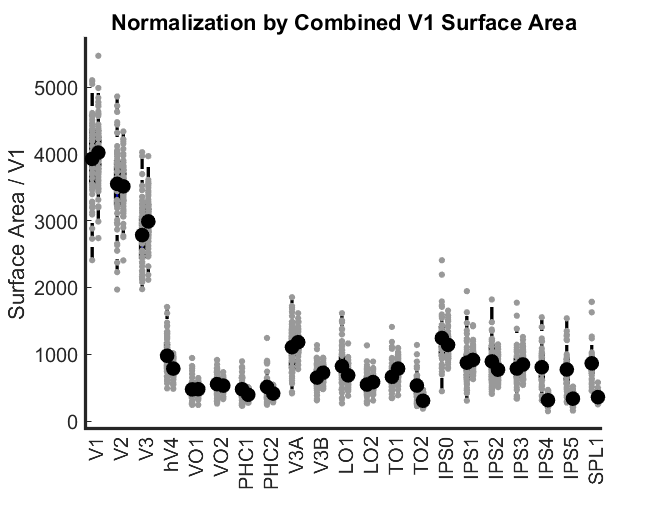

human_dorsal_idx =  [1, 2, 3, 9, 10, 15:21];
human_lateral_idx = [1, 2, 3, 11:14];
human_ventral_idx = [1, 2, 3, 4:8];

v2_idx = 2;
v3_idx = 3;
v4_idx = 4;
dorsal_idx = human_dorsal_idx(4:5);
parietal_idx = human_dorsal_idx(6:end);
lateral_idx = human_lateral_idx(4:end);
ventral_idx = human_ventral_idx(5:end);
human_area_idx = {v2_idx,v3_idx,v4_idx,ventral_idx,dorsal_idx,lateral_idx,parietal_idx};

EVCrois_human=1:6; EVCcolor=[0.1 0.6 1];
V4rois_human=7; V4color=[1 0.2 1];
ventralrois_human=8:11; ventralcolor=[1 0.2 0.2];
dorsalrois_human=12:13; dorsalcolor=[1 .8 0];
lateralrois_human=15:18; lateralcolor=[0 1 0];
parietalrois_human=19:25; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
allrois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human};
alllabels_human = human_data.labels;
use_colorscale_indiv_all=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

evccolor=[0 0 0.7];
v4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0];
lateralcolor=[0.2784    0.5216    0.1451];
parietalcolor=[0 0.7 0.7];
use_colorscale_prob_all=[repmat(evccolor,length(EVCrois_human),1);...
    repmat(v4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

alllabs = cat(2,{'V1','V2','V3'},alllabels_human(7:end));

use_colorscale_inv_indiv=flipud(use_colorscale_indiv_all);
use_colorscale_inv_prob=flipud(use_colorscale_prob_all);


% pad array with nan to get the same size as humans
concat_data = [];
concat_colorscale = [];
for i = 1:size(SA_sumvd_human,1)
    concat_data = [concat_data; SA_sumvd_human(i,:); SA_sumvd_human_prob(i,:)];
    concat_colorscale = [concat_colorscale;use_colorscale_inv_indiv(i,:);use_colorscale_inv_prob(i,:)];
end

% set groupings by species and areas to use factorgap in boxplot
g1 = sort([1:size(SA_sumvd_human,1),1:size(SA_sumvd_human,1)]);
g2 = repmat(1:2,[1,size(SA_sumvd_human,1)]);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',5,'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
ax.FontSize = 15;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabs,'fontsize',12);
% xlabel('Visual Areas');
ylabel('Surface Area / V1');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

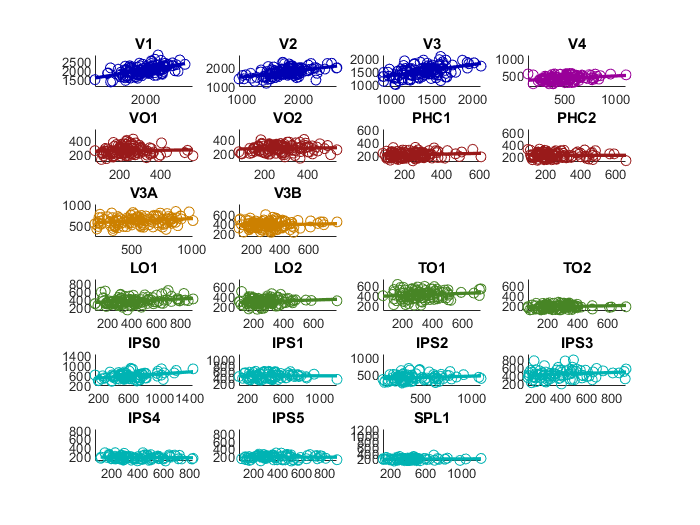

figure();
for i = 1:4
    subplot(6,4,i)
    include = ~isnan(SA_catvd_human(i,:)) & ~isnan(SA_catvd_human_prob(i,:));
    x = SA_catvd_human(i,include);
    y = SA_catvd_human_prob(i,include);
    plot(x,y,'o','Color',use_colorscale_prob_all(i+3,:))
    % Get coefficients of a line fit through the data.
    coefficients = polyfit(x, y, 1);
    % Create a new x axis with exactly 1000 points (or whatever you want).
    xFit = linspace(min(x), max(x), 1000);
    % Get the estimated yFit value for each of those 1000 new x locations.
    yFit = polyval(coefficients , xFit);
    % Plot everything.
    hold on; % Set hold on so the next plot does not blow away the one we just drew.
    plot(xFit, yFit, '-','Color',use_colorscale_prob_all(i+3,:), 'LineWidth', 2); % Plot fitted line.
    xlim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    ylim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    box off
    title(alllabels_human_merge{i})
end
for i = 5:8
    subplot(6,4,i)
    include = ~isnan(SA_catvd_human(i,:)) & ~isnan(SA_catvd_human_prob(i,:));
    x = SA_catvd_human(i,include);
    y = SA_catvd_human_prob(i,include);
    plot(x,y,'o','Color',use_colorscale_prob_all(i+3,:))
    % Get coefficients of a line fit through the data.
    coefficients = polyfit(x, y, 1);
    % Create a new x axis with exactly 1000 points (or whatever you want).
    xFit = linspace(min(x), max(x), 1000);
    % Get the estimated yFit value for each of those 1000 new x locations.
    yFit = polyval(coefficients , xFit);
    % Plot everything.
    hold on; % Set hold on so the next plot does not blow away the one we just drew.
    plot(xFit, yFit, '-','Color',use_colorscale_prob_all(i+3,:), 'LineWidth', 2); % Plot fitted line.
    xlim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    ylim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    box off
    title(alllabels_human_merge{i})
end
for i = 9:10
    subplot(6,4,i)
    include = ~isnan(SA_catvd_human(i,:)) & ~isnan(SA_catvd_human_prob(i,:));
    x = SA_catvd_human(i,include);
    y = SA_catvd_human_prob(i,include);
    plot(x,y,'o','Color',use_colorscale_prob_all(i+3,:))
    % Get coefficients of a line fit through the data.
    coefficients = polyfit(x, y, 1);
    % Create a new x axis with exactly 1000 points (or whatever you want).
    xFit = linspace(min(x), max(x), 1000);
    % Get the estimated yFit value for each of those 1000 new x locations.
    yFit = polyval(coefficients , xFit);
    % Plot everything.
    hold on; % Set hold on so the next plot does not blow away the one we just drew.
    plot(xFit, yFit, '-','Color',use_colorscale_prob_all(i+3,:), 'LineWidth', 2); % Plot fitted line.
    xlim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    ylim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    box off
    title(alllabels_human_merge{i})
end
for i = 11:14
    subplot(6,4,i+2)
    include = ~isnan(SA_catvd_human(i,:)) & ~isnan(SA_catvd_human_prob(i,:));
    x = SA_catvd_human(i,include);
    y = SA_catvd_human_prob(i,include);
    plot(x,y,'o','Color',use_colorscale_prob_all(i+3,:))
    % Get coefficients of a line fit through the data.
    coefficients = polyfit(x, y, 1);
    % Create a new x axis with exactly 1000 points (or whatever you want).
    xFit = linspace(min(x), max(x), 1000);
    % Get the estimated yFit value for each of those 1000 new x locations.
    yFit = polyval(coefficients , xFit);
    % Plot everything.
    hold on; % Set hold on so the next plot does not blow away the one we just drew.
    plot(xFit, yFit, '-','Color',use_colorscale_prob_all(i+3,:), 'LineWidth', 2); % Plot fitted line.
    xlim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    ylim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    box off
    title(alllabels_human_merge{i})
end
for i = 15:18
    subplot(6,4,i+2)
    include = ~isnan(SA_catvd_human(i,:)) & ~isnan(SA_catvd_human_prob(i,:));
    x = SA_catvd_human(i,include);
    y = SA_catvd_human_prob(i,include);
    plot(x,y,'o','Color',use_colorscale_prob_all(i+3,:))
    % Get coefficients of a line fit through the data.
    coefficients = polyfit(x, y, 1);
    % Create a new x axis with exactly 1000 points (or whatever you want).
    xFit = linspace(min(x), max(x), 1000);
    % Get the estimated yFit value for each of those 1000 new x locations.
    yFit = polyval(coefficients , xFit);
    % Plot everything.
    hold on; % Set hold on so the next plot does not blow away the one we just drew.
    plot(xFit, yFit, '-','Color',use_colorscale_prob_all(i+3,:), 'LineWidth', 2); % Plot fitted line.
    xlim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    ylim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    box off
    title(alllabels_human_merge{i})
end
for i = 19:21
    subplot(6,4,i+2)
    include = ~isnan(SA_catvd_human(i,:)) & ~isnan(SA_catvd_human_prob(i,:));
    x = SA_catvd_human(i,include);
    y = SA_catvd_human_prob(i,include);
    plot(x,y,'o','Color',use_colorscale_prob_all(i+3,:))
    % Get coefficients of a line fit through the data.
    coefficients = polyfit(x, y, 1);
    % Create a new x axis with exactly 1000 points (or whatever you want).
    xFit = linspace(min(x), max(x), 1000);
    % Get the estimated yFit value for each of those 1000 new x locations.
    yFit = polyval(coefficients , xFit);
    % Plot everything.
    hold on; % Set hold on so the next plot does not blow away the one we just drew.
    plot(xFit, yFit, '-','Color',use_colorscale_prob_all(i+3,:), 'LineWidth', 2); % Plot fitted line.
    xlim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    ylim([min([min(x,[],'all') min(y,[],'all')]) max([max(x,[],'all') max(y,[],'all')])])
    box off
    title(alllabels_human_merge{i})
end

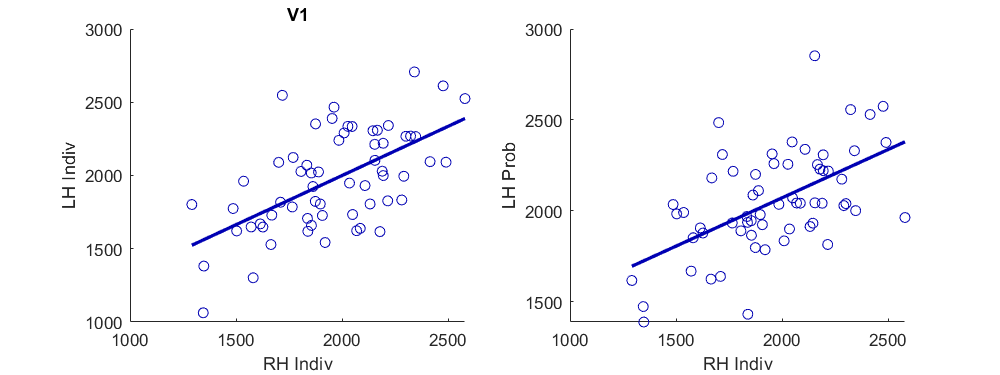

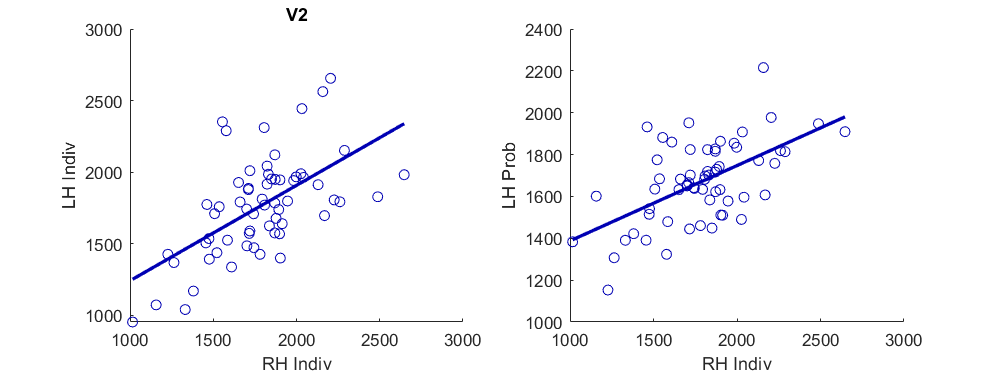

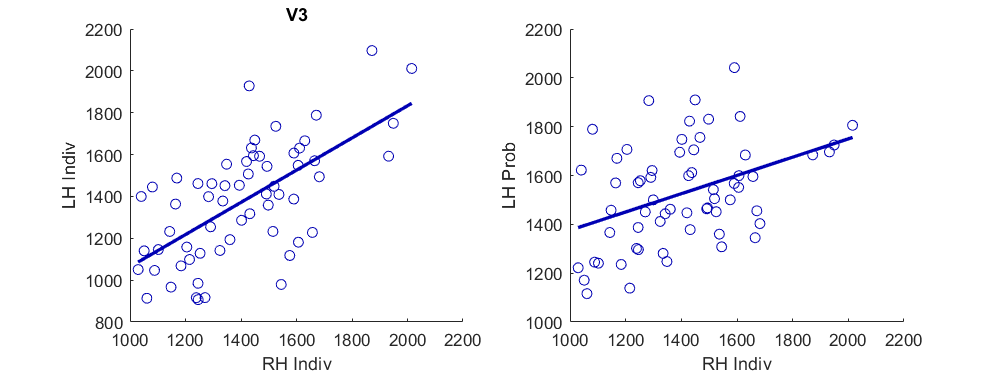

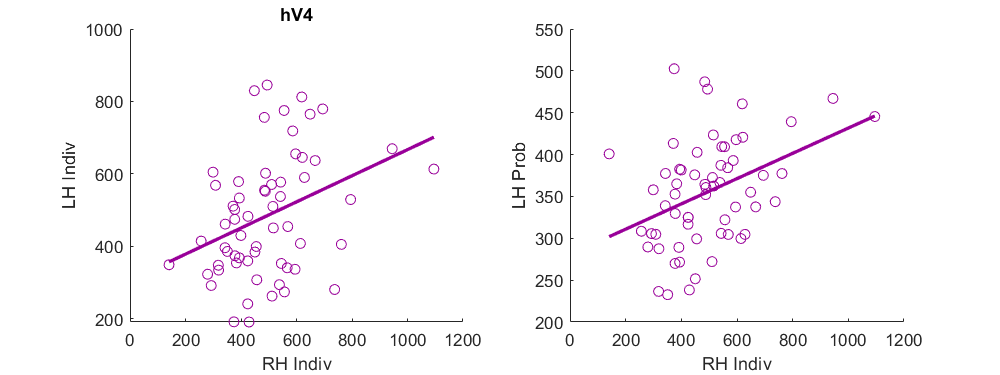

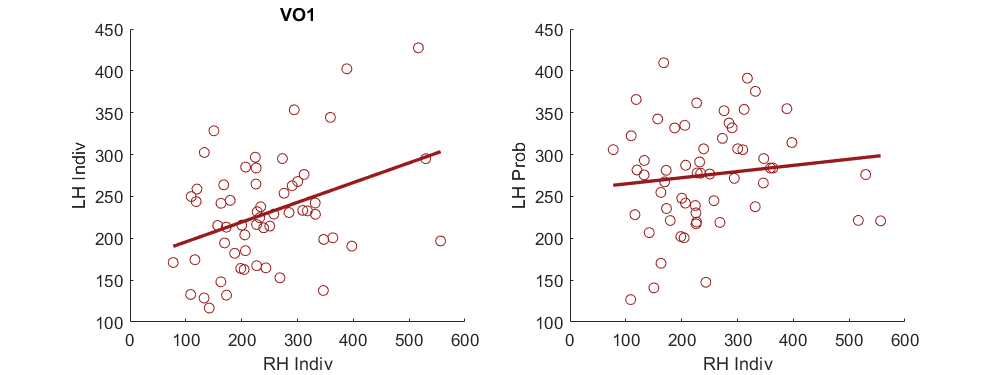

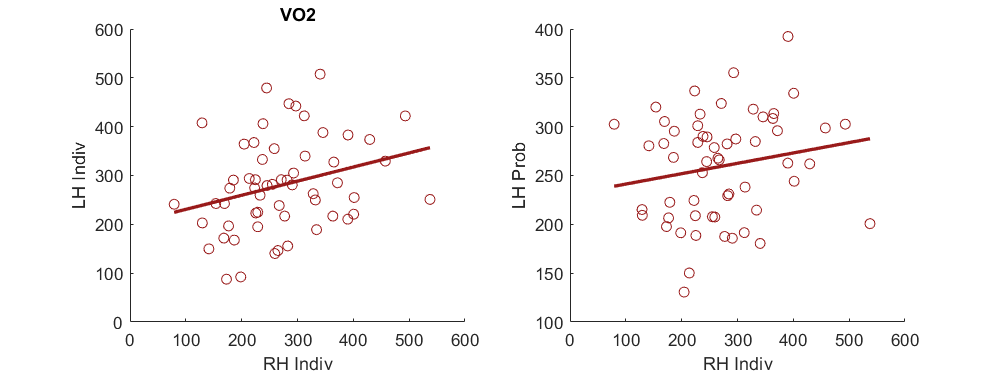

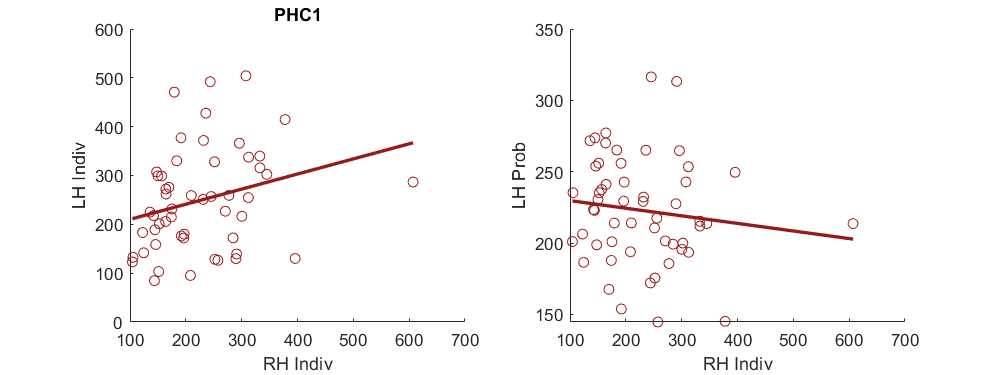

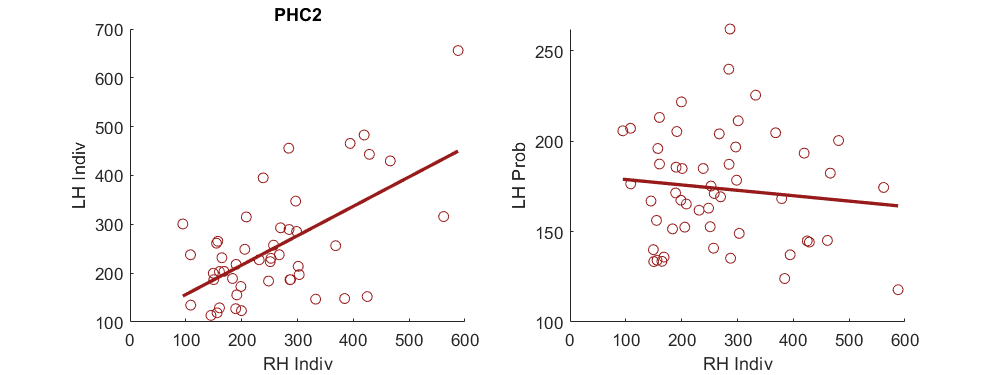

nSubj = size(SA_catvd_human,2);
for i = 1:size(SA_catvd_human,1)
    figure('Position',[10 10 800 300]);
    subplot(1,2,1)
    
    include = find(~isnan(SA_catvd_human(i,1:nSubj/2)) & ~isnan(SA_catvd_human(i,nSubj/2+1:end)));
    x = SA_catvd_human(i,include);
    y = SA_catvd_human(i,include+nSubj/2);
    plot(x,y,'o','Color',use_colorscale_prob_all(i+3,:))
    % Get coefficients of a line fit through the data.
    coefficients = polyfit(x, y, 1);
    % Create a new x axis with exactly 1000 points (or whatever you want).
    xFit = linspace(min(x), max(x), 1000);
    % Get the estimated yFit value for each of those 1000 new x locations.
    yFit = polyval(coefficients , xFit);
    % Plot everything.
    hold on; % Set hold on so the next plot does not blow away the one we just drew.
    plot(xFit, yFit, '-','Color',use_colorscale_prob_all(i+3,:), 'LineWidth', 2); % Plot fitted line.
    
    title(alllabs{i})
    xlabel('RH Indiv')
    ylabel('LH Indiv')
    box off
    
    subplot(1,2,2)
    
    include = find(~isnan(SA_catvd_human(i,1:nSubj/2)) & ~isnan(SA_catvd_human_prob(i,nSubj/2+1:end)));
    x = SA_catvd_human(i,include);
    y = SA_catvd_human_prob(i,include+nSubj/2);
    plot(x,y,'o','Color',use_colorscale_prob_all(i+3,:))
    % Get coefficients of a line fit through the data.
    coefficients = polyfit(x, y, 1);
    % Create a new x axis with exactly 1000 points (or whatever you want).
    xFit = linspace(min(x), max(x), 1000);
    % Get the estimated yFit value for each of those 1000 new x locations.
    yFit = polyval(coefficients , xFit);
    % Plot everything.
    hold on; % Set hold on so the next plot does not blow away the one we just drew.
    plot(xFit, yFit, '-','Color',use_colorscale_prob_all(i+3,:), 'LineWidth', 2); % Plot fitted line.
    
    xlabel('RH Indiv')
    ylabel('LH Prob')
    box off
end

alllabels_human_merge = {'V1','V2','V3','V4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2','IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};

EVCcolor=[0 0 0.7];
V4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralcolor=[0.2784    0.5216    0.1451];
parietalcolor=[0 0.7 0.7];
frontalcolor=[.4 0 .4];
use_colorscale_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];%LGNcolor];

EVCcolor=[0.1 0.6 1];
V4color=[1 0.2 1];
ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
lateralcolor=[0 1 0];
parietalcolor=[0 1 1];
use_colorscale_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];

% should probably do some bootstrapping here
all_area_corr_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
all_area_pval_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
stats_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge),2);
for i = 1:length(alllabels_human_merge)
    for j = 1:length(alllabels_human_merge)
        include = ~isnan(SA_catvd_human_prob(i,:)) & ~isnan(SA_catvd_human_prob(j,:));
        [r,p] = corr(SA_catvd_human_prob(i,include)',SA_catvd_human_prob(j,include)');
        temp = bootci(1000,@corr,[SA_catvd_human_prob(i,include)',SA_catvd_human_prob(j,include)']);
        stats_human(i,j,:) = temp(:,1,2);
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_human_reg = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
all_area_pval_human_reg = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
stats_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge),2);
for i = 1:length(alllabels_human_merge)
    for j = 1:length(alllabels_human_merge)
        
        include = ~isnan(SA_catvd_human_prob(i,:)) & ~isnan(SA_catvd_human_prob(j,:));
        
        human_area_resid1 = fitlm(total_catvd_human_prob(include),SA_catvd_human_prob(i,include));
        human_area_resid2 = fitlm(total_catvd_human_prob(include),SA_catvd_human_prob(j,include));
        
        [r,p] = corr(human_area_resid1.Residuals.Raw,human_area_resid2.Residuals.Raw);
        temp = bootci(1000,@corr,[human_area_resid1.Residuals.Raw,human_area_resid2.Residuals.Raw]);
        stats_human(i,j,:) = temp(:,1,2);
        all_area_pval_human_reg(i,j) = p;
        all_area_corr_human_reg(i,j) = r;
        
    end
end



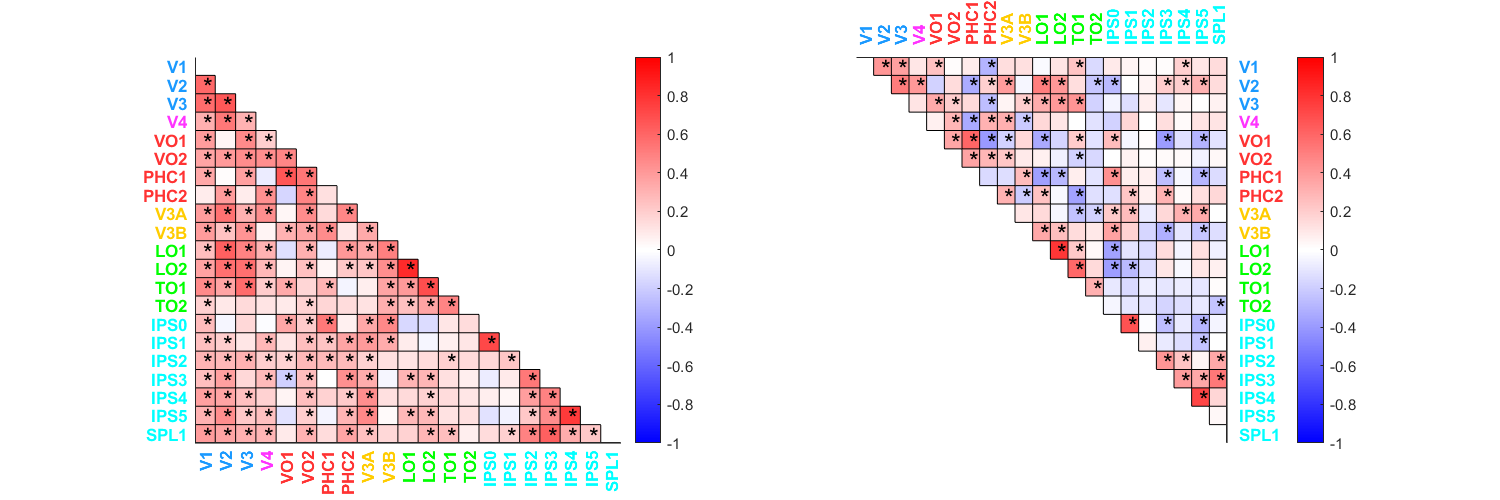

figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
subplot(1,2,1)
Z = ones(size(all_area_corr_human,1), size(all_area_corr_human,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_human);
lower_tri(1:length(lower_tri)+1:end) = 0;
p_tri = tril(all_area_pval_human);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;
alphadata = double(lower_tri ~= 0);

h1 = imagesc(all_area_corr_human);
h1.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_human,1)
    for j = 1:size(all_area_corr_human,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_human)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_human)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')
end
Xticklabels_new = cell(size(alllabels_human_merge));
Yticklabels_new = cell(size(alllabels_human_merge));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], EVCcolor);
end
for i = 4
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], V4color);
end
for i = 5:8
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], ventralcolor);
end
for i = 9:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], dorsalcolor);
end
for i = 11:14
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], lateralcolor);
end
for i = 15:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], parietalcolor);
end

ax = gca;
set(ax, 'XTick',1:length(alllabels_human_merge),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_human_merge),'YTickLabel',Yticklabels_new)
% set(ax,'xaxisLocation','top')
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];

colormap(redblue);c = colorbar;caxis([-1 1]);

subplot(1,2,2)
Z = ones(size(all_area_corr_human_reg,1), size(all_area_corr_human_reg,2), 3);  %black background
image(Z);
hold on;
upper_tri = triu(all_area_corr_human_reg);
upper_tri(1:length(upper_tri)+1:end) = 0;
p_tri = tril(all_area_pval_human_reg);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;
alphadata = double(upper_tri ~= 0);

h1 = imagesc(all_area_corr_human_reg);
h1.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_human_reg,1)
    for j = 1:size(all_area_corr_human_reg,2)
        if p_tri(j,i)<0.05
            text(j-0.1,i+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_human_reg)
        plot([j+0.5 length(all_area_corr_human_reg)+0.5],[j+0.5 j+0.5],'k')
        end
    end
    plot([i+0.5 i+0.5],[i+0.5 0],'k')
end

ax = gca;
set(ax, 'XTick',1:length(alllabels_human_merge),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_human_merge),'YTickLabel',Yticklabels_new)
set(ax,'xaxisLocation','top')
set(ax,'yaxisLocation','right')

ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];
box off;

colormap(redblue);c = colorbar;caxis([-1 1]);